# Bicycle model Simulink experiment

clear; clc; close;

load exampleMaps.mat;


chosenMap = QCarMap;
map = binaryOccupancyMap(chosenMap)

map =   binaryOccupancyMap with properties:

   mapLayer Properties
              LayerName: 'binaryLayer'
               DataType: 'logical'
           DefaultValue: 0
    GridLocationInWorld: [0 0]
      GridOriginInLocal: [0 0]
     LocalOriginInWorld: [0 0]
             Resolution: 1
               GridSize: [20 20]
           XLocalLimits: [0 20]
           YLocalLimits: [0 20]
           XWorldLimits: [0 20]
           YWorldLimits: [0 20]



distMin = 0.1;
distMax = 3;

speedMax = 0.2;

steeringRange = 0.5;

startLoc = randLoc(chosenMap);
startOrient = rand*2*pi;

startPose = [startLoc startOrient]

startPose =    16.5000   18.5000    0.7979




goalLoc = randLoc(chosenMap);
goalOrient = rand*2*pi;

goalPose = [goalLoc goalOrient]

goalPose =    18.5000   12.5000    0.6129


### Setup DDPG Agent

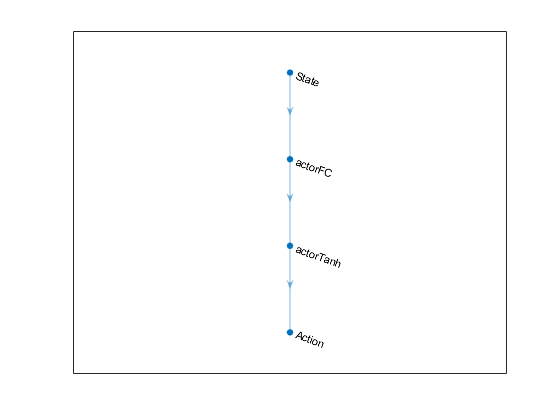

% Setup environnement
obsInfo = rlNumericSpec([2 1],...
    'LowerLimit',[0 0]',...
    'UpperLimit',[1 1]');
obsInfo.Name = 'observation';
obsInfo.Description = 'minimum distance to wall and index of this distance';
numObservations = obsInfo.Dimension(1);

actInfo = rlNumericSpec([2 1],...
    'LowerLimit',[-1 -1]',...
    'UpperLimit',[1 1]');
actInfo.Name = 'actions';
actInfo.Description = 'speed, steering';
numActions = actInfo.Dimension(1);

env = rlSimulinkEnv('RLBicycleSimulinkP2P','RLBicycleSimulinkP2P/RL Agent',...
    obsInfo,actInfo);

env.ResetFcn = @(in)localResetFcn(in, chosenMap);
Ts = 1.0;
Tf = 1000;
rng(0)

% Setup acteur
actorNetwork = [
    featureInputLayer(numObservations,'Normalization','none','Name','State')
    fullyConnectedLayer(3, 'Name','actorFC')
    tanhLayer('Name','actorTanh')
    fullyConnectedLayer(numActions,'Name','Action')
    ];

actorPlot = layerGraph();
actorPlot = addLayers(actorPlot,actorNetwork);

figure
plot(actorPlot)

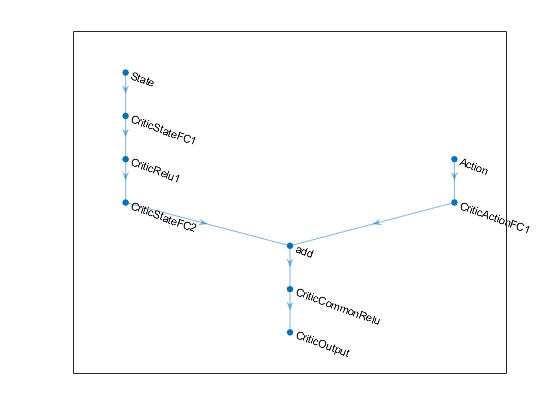


actorOptions = rlRepresentationOptions('LearnRate',1e-04,'GradientThreshold',1);
actor = rlDeterministicActorRepresentation(actorNetwork,obsInfo,actInfo,'Observation',{'State'},'Action',{'Action'},actorOptions);

% Setup critique
statePath = [
    featureInputLayer(numObservations,'Normalization','none','Name','State')
    fullyConnectedLayer(50,'Name','CriticStateFC1')
    reluLayer('Name','CriticRelu1')
    fullyConnectedLayer(25,'Name','CriticStateFC2')];
actionPath = [
    featureInputLayer(numActions,'Normalization','none','Name','Action')
    fullyConnectedLayer(25,'Name','CriticActionFC1')];
commonPath = [
    additionLayer(2,'Name','add')
    reluLayer('Name','CriticCommonRelu')
    fullyConnectedLayer(1,'Name','CriticOutput')];

criticNetwork = layerGraph();
criticNetwork = addLayers(criticNetwork,statePath);
criticNetwork = addLayers(criticNetwork,actionPath);
criticNetwork = addLayers(criticNetwork,commonPath);
criticNetwork = connectLayers(criticNetwork,'CriticStateFC2','add/in1');
criticNetwork = connectLayers(criticNetwork,'CriticActionFC1','add/in2');

figure
plot(criticNetwork)


criticOpts = rlRepresentationOptions('LearnRate',1e-04,'GradientThreshold',1);

critic = rlQValueRepresentation(criticNetwork,obsInfo,actInfo,'Observation',{'State'},'Action',{'Action'},criticOpts);

%Setup agent
agentOpts = rlDDPGAgentOptions(...
    'SampleTime',Ts,...
    'TargetSmoothFactor',1e-3,...
    'DiscountFactor',1.0, ...
    'MiniBatchSize',64, ...
    'ExperienceBufferLength',1e6); 
agentOpts.NoiseOptions.StandardDeviation = 0.5;
agentOpts.NoiseOptions.StandardDeviationDecayRate = 1e-5;

agent = rlDDPGAgent(actor,critic,agentOpts);

### Load environment

open_system('RLBicycleSimulinkP2P.slx')

### Train agent

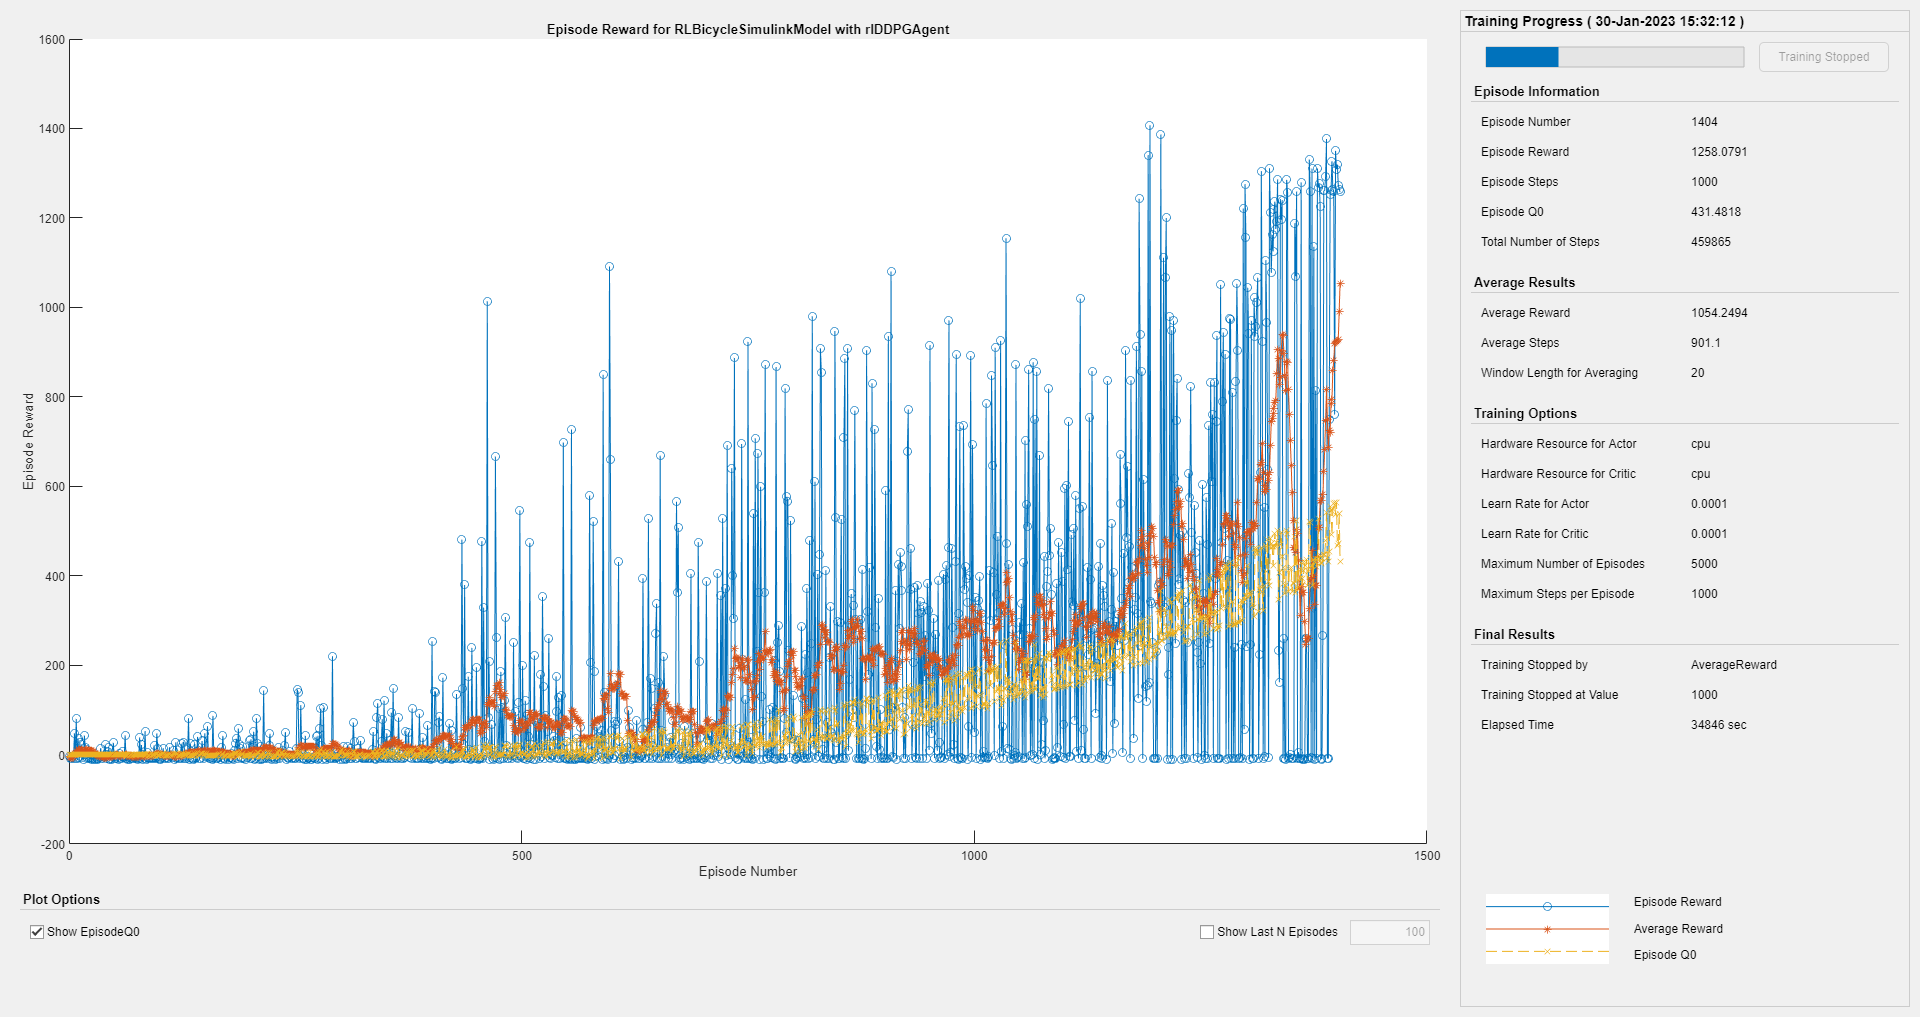

% Parametres surement a changer
maxepisodes = 5000;
maxsteps = ceil(Tf/Ts);
trainOpts = rlTrainingOptions(...
    'MaxEpisodes',maxepisodes, ...
    'MaxStepsPerEpisode',maxsteps, ...
    'ScoreAveragingWindowLength',20, ...
    'Verbose',false, ...
    'Plots','training-progress',...
    'StopTrainingCriteria','AverageReward',...
    'StopTrainingValue',2000);

doTraining = true;

if doTraining
    % Train the agent
    trainingStats = train(agent,env,trainOpts);
else
    % Load the pretrained agent for the example.
    load('RL_agent_v3.mat','agent');
end

### Validation : Run model

startLoc = randLoc(chosenMap);
startOrient = rand*2*pi;

startPose = [startLoc startOrient]

startPose =     5.5000   11.5000    5.8897



simulation = sim('RLBicycleSimulinkP2P.slx');

#### Get all robot poses

robotPose = simulation.BicyclePose;

#### Print map of movements

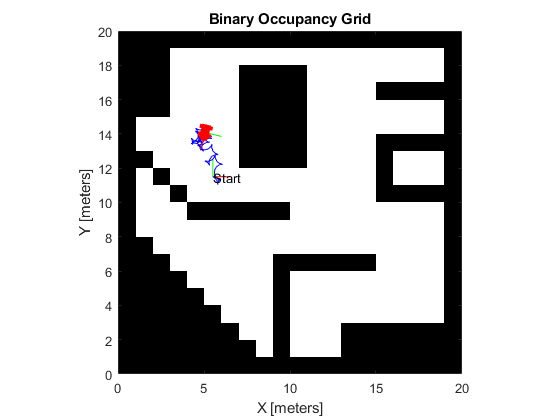

numRobots = size(robotPose, 2) / 3;
thetaIdx = 3;

% Translation
xyz = robotPose;
xyz(:, thetaIdx) = 0;

% Rotation in XYZ euler angles
theta = robotPose(:,thetaIdx);
thetaEuler = zeros(size(robotPose, 1), 3 * size(theta, 2));
thetaEuler(:, end) = theta;

show(map)
hold on;

% Plot Start Location
plotTransforms([startLoc, 0], eul2quat([0, 0, 0]))
text(startLoc(1), startLoc(2), 2, 'Start');

% Plot Robot's XY locations
plot(robotPose(:, 1), robotPose(:, 2), 'b')

% Plot Robot's pose as it traverses the path
quat = eul2quat(thetaEuler(size(xyz, 1), :), 'xyz');
plotTransforms(xyz(size(xyz, 1),:), quat, 'MeshFilePath',...
    'groundvehicle.stl');

hold off;
view([0 90])

function in = localResetFcn(in, map)
    % randomize initial after collision
    spawn = [randLoc(map) rand*2*pi];
    goal = [randLoc(map) rand*2*pi];
    sprintInitLoc = sprintf('[%s]', num2str(spawn));
    sprintGoalLoc = sprintf('[%s]', num2str(goal));
    blkG = 'RLBicycleSimulinkP2P/Goal';
    in = setBlockParameter(in,blkG,'ConstantValue',sprintGoalLoc);
    blk = 'RLBicycleSimulinkP2P/Bicycle Model/Integrator';
    in = setBlockParameter(in,blk,'InitialCondition',sprintInitLoc);
end

function loc = randLoc(map)
    isFree = false;
    sizeMap = size(map);
    while ~isFree
        % inversion de dimensions entre matrice et binaryMap
        loc = [randi([1, sizeMap(2)]) randi([1, sizeMap(1)])];
        transform = changeRepere(loc, sizeMap);
        % vérifie si l'endroit d'apparition est libre
        if map(transform(1), transform(2))==0
            isFree = true;
        end
    end
    % -0.5 sur chaque coordonnée pour ne pas apparaître collé à un mur
    loc = loc-0.5;
end

function transform = changeRepere(loc, sizeMap)
    % si loc vaut [3 2] => checker valeur [hauteur-1 3]
    % si loc vaut [largeur hauteur-2] => checker valeur [3 largeur]
    % si loc vaut [x y] => checker valeur [hauteur-(y-1) x]
    x = loc(1);
    y = loc(2);
    transform = [sizeMap(1)-(y-1) x];
end